# Sequence Classification Using 1-D Convolutions

This example shows how to classify sequence data using a 1-D convolutional neural network.

To train a deep neural network to classify sequence data, you can use a 1-D convolutional neural network. A 1-D convolutional layer learns features by applying sliding convolutional filters to 1-D input. Using 1-D convolutional layers can be faster than using recurrent layers because convolutional layers can process the input with a single operation. By contrast, recurrent layers must iterate over the time steps of the input. However, depending on the network architecture and filter sizes, 1-D convolutional layers might not perform as well as recurrent layers, which can learn long-term dependencies between time steps.

This example uses the Japanese Vowels data set described in [1] and [2]. This example trains a 1-D convolutional neural network to recognize the speaker given time series data representing two Japanese vowels spoken in succession. The training data contains time series data for nine speakers. Each sequence has 12 features and varies in length. The data set contains 270 training observations and 370 test observations.

## Load Sequence Data

Load the Japanese Vowels training data. The predictor data is a cell array containing sequences of varying length with 12 features. The target data is a categorical vector of labels "1","2",...,"9", which correspond to the nine speakers. The predictor sequences are matrices with 12 rows (one row for each feature) and a varying number of columns (one column for each time step).

[XTrain,TTrain] = japaneseVowelsTrainData;
[XValidation,TValidation] = japaneseVowelsTestData;

View the first few training sequences.

XTrain(1:5)

ans = 5×1 cell array
    {12×20 double}
    {12×26 double}
    {12×22 double}
    {12×20 double}
    {12×21 double}


Visualize the first time series in a plot. Each line corresponds to a feature.

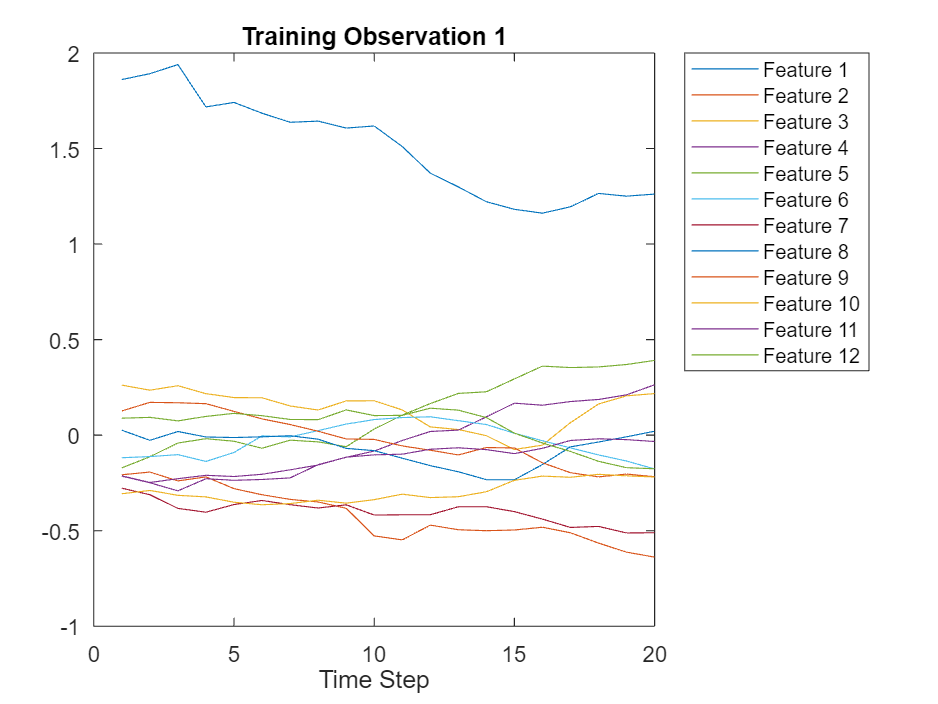

figure
plot(XTrain{1}')
xlabel("Time Step")
title("Training Observation 1")
numFeatures = size(XTrain{1},1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")

View the number of classes in the training data.

classes = categories(TTrain);
numClasses = numel(classes)

numClasses = 9

## Define 1-D Convolutional Network Architecture

Define the 1-D convolutional neural network architecture. 

- Specify the input size as the number of features of the input data. 

- Specify two blocks of 1-D convolution, ReLU, and layer normalization layers, where the convolutional layer has a filter size of 3. Specify 32 and 64 filters for the first and second convolutional layers, respectively. For both convolutional layers, left-pad the inputs such that the outputs have the same length (causal padding).

- To reduce the output of the convolutional layers to a single vector, use a 1-D global average pooling layer.

- To map the output to a vector of probabilities, specify a fully connected layer with an output size matching the number of classes, followed by a softmax layer and a classification layer.

filterSize = 3;
numFilters = 32;
numHiddenUnits = 100;
layers = [ ...
    sequenceInputLayer(numFeatures)
    convolution1dLayer(filterSize,numFilters,Padding="causal")
    % reluLayer
    % layerNormalizationLayer
    % convolution1dLayer(filterSize,2*numFilters,Padding="causal")
    % reluLayer
    % layerNormalizationLayer
    globalAveragePooling1dLayer
    lstmLayer(numHiddenUnits,OutputMode="last")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

## Specify Training Options

Specify the training options:

- Train using the Adam optimizer.

- Train with a mini-batch size of 27 for 15 epochs.

- Left-pad the sequences.

- Validate the network using the validation data.

- Monitor the training progress in a plot and suppress the verbose output.

miniBatchSize = 27;

options = trainingOptions("adam", ...
    MiniBatchSize=miniBatchSize, ...
    MaxEpochs=100, ...
    SequencePaddingDirection="left", ...
    ValidationData={XValidation,TValidation}, ...
    Plots="training-progress", ...
    Verbose=0);

## Train Network

Train the network with the specified training options using the `trainNetwork` function.

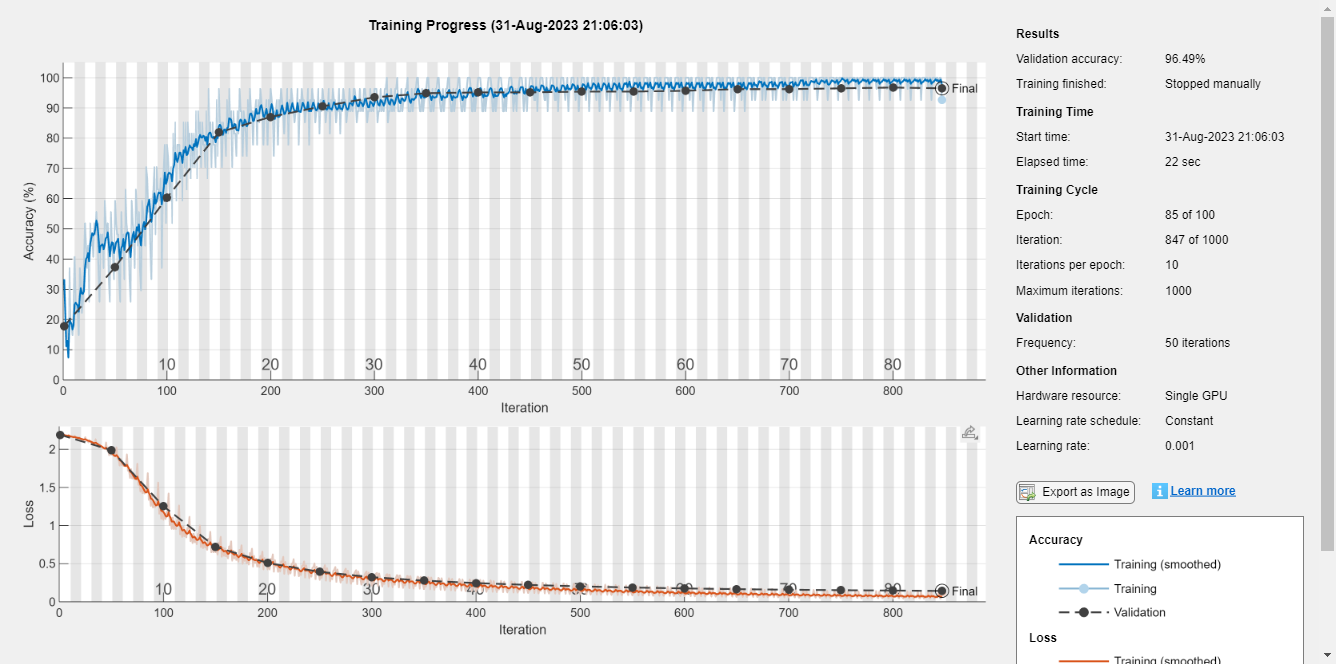

net = trainNetwork(XTrain,TTrain,layers,options);

## Test Network

Classify the validation data using the same mini-batch size and sequence padding options used for training.

% YPred = classify(net,XValidation, ...
%     MiniBatchSize=miniBatchSize, ...
%     SequencePaddingDirection="left");
for i = 1:length(XValidation)
    YPred(i) = classify(net,XValidation{i,1},SequencePaddingDirection="left");
end

Calculate the classification accuracy of the predictions.

acc = mean(YPred == TValidation)

acc = 0.9378

Visualize the predictions in a confusion matrix.

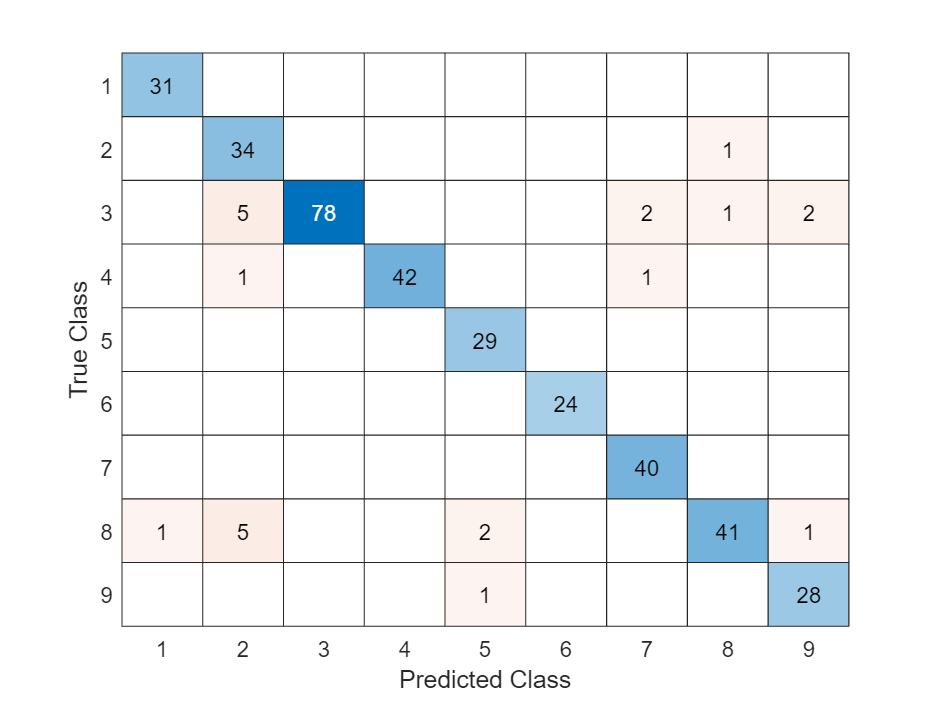

confusionchart(TValidation,YPred)

## References

[1] Kudo, Mineichi, Jun Toyama, and Masaru Shimbo. “Multidimensional Curve Classification Using Passing-through Regions.” Pattern Recognition Letters 20, no. 11–13 (November 1999): 1103–11. [https://doi.org/10.1016/S0167-8655(99)00077-X](https://doi.org/10.1016/S0167-8655(99)00077-X) 

[2] Kudo, Mineichi, Jun Toyama, and Masaru Shimbo. "Japanese Vowels Data Set." Distributed by UCI Machine Learning Repository. [https://archive.ics.uci.edu/ml/datasets/Japanese+Vowels](https://archive.ics.uci.edu/ml/datasets/Japanese+Vowels) 

*Copyright 2021 The MathWorks, Inc.*